clear
clc

% Initial conditions at BDC
Ti = 300;       % [K]
Pi = 1;         % [atm]
Pi = Pi*101325; % [atm -> Pa]
Vi = 3.68E-4;   % [m^3]

% Given conditions from problem
AF = 16;        % Air-fuel ratio
rc = 10;        % Compression ratio
phi = 1;        % Stoichoimetric condition

% Known constants
Ru = 8314;      % [J/kg-K]
gamma = 1.4;

% Initial conditions at TDC
Vf = Vi/rc

Vf = 3.6800e-05

T0 = Ti*(rc^(gamma-1))

T0 = 753.5659

P0 = Pi*(rc^gamma)

P0 = 2.5452e+06


% Initial mol fraction of components [unitless]
x_Ox_0 = (AF/phi)/((AF/phi)+1)

x_Ox_0 = 0.9412

x_F_0 = 1-x_Ox_0

x_F_0 = 0.0588


% Initial molar concentrations of components 
Ox_0 = x_Ox_0*(P0/(Ru*T0))  % [kmol/m^3]

Ox_0 = 0.3823

F_0 = x_F_0*(P0/(Ru*T0))    % [kmol/m^3]

F_0 = 0.0239

Pr_0 = 0 

Pr_0 = 0


y0 = [F_0,Ox_0,Pr_0,T0,P0];
tspan = [0 0.004];

[t,y] = ode45(@ConstVol, tspan, y0);

Fuel = y(:,1);
Oxygen = y(:,2);
Prod = y(:,3);
Temp = y(:,4);
Press = y(:,5);

tiledlayout(3,1)
plot(t,Fuel,t,Oxygen,t,Prod)

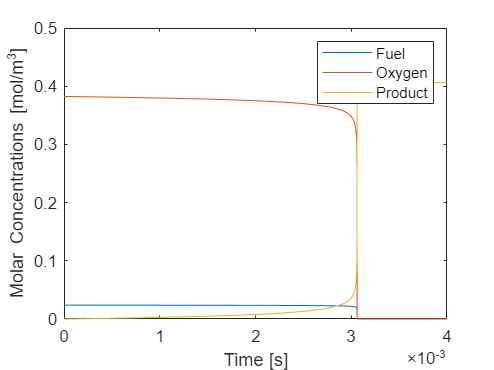

legend('Fuel','Oxygen','Product')
ylabel('Molar Concentrations [mol/m^3]')
xlabel('Time [s]')


plot(t,Temp)

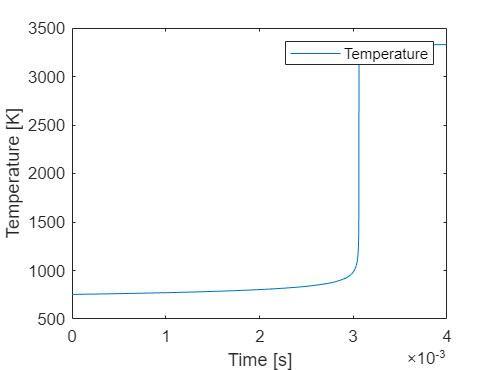

legend('Temperature')
ylabel('Temperature [K]')
xlabel('Time [s]')


plot(t,Press)

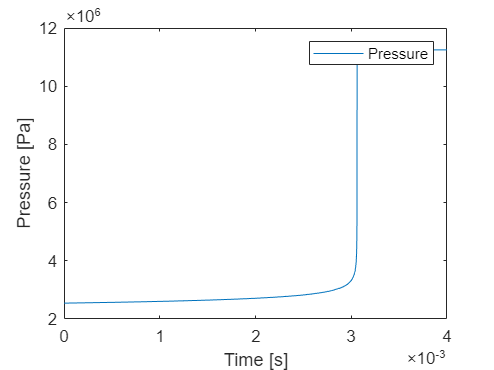

legend('Pressure')
ylabel('Pressure [Pa]')
xlabel('Time [s]')